# ***Assignment 1***

#### `Table of Contents`

- Read an image into workspace variable

- Display the image

- Apply image processing filters to the image

- Display the result

- Saving the resulting image to a .png file

# Read an image

% reading an image
image = imread('img.jpg')

image = 3770×5306×3 uint8 array
image(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     2     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     0     0     0     0     1     1     0     0     0     0    

# Display the image

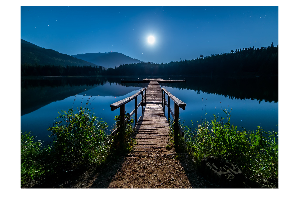

% displaying the image
imshow(image);

# Applying the filters to the image

% applying image processing filters to the image
X = fspecial('laplacian',0);
Y = fspecial('motion', 110, 130);
final = imfilter(image,Y);

# Displaying the result

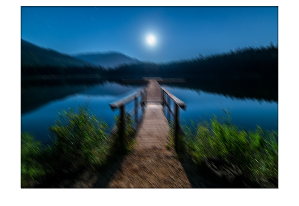

% displaying the result
figure, imshow(final);

# Saving the image to a .png file

% saving the result
imwrite(final,'result.png')

**LAPLACIAN FILTER : **

This filter highlights the edges and detects the transitions of the images which are having sudden intensity.

**MOTION FILTER :**

This filter is used to blur the images according to our requirements based on the given length. 